# Basic vs Optimized Goertzel Algorithm

## I-  Goertzel Algorithm

The Goertzel algorithm can perform tone detection using much less CPU horsepower than Fast Fourier Transform (FFT). Most engineergs are familiar with the FFT and would have little trouble using a "canned" FFT routine to detect one or more tones in an audio signal. What many don't know, however, is that if you only need to detect a few frequencies, a much faster method is called The Goertzel Algorithm.

## II-  Basic Goertzel

The basic Goertzel algorithm gives you real and imaginary frequency components as a regular Discrete Fourier Transform (DFT) or FFT would. Magnitude and Phase can be computed from the real/imaginary pair.

## III-  Optimized Goertzel

The optimized Goertzel is even faster and simpler than the basic algorithm, but doesn't give you the real and imaginary frequency components. Instead, It gives you the relative magnitude squared. So, you can take the square root of this result to get the relative magnitude, but there is no way to obtain the phase.

Before we start implemting the actual Goertzel, we must do some preliminary steps such as creating our own constants variables and signal.

clear                                  % Clear all data stored in variables
Am = 1;                                % 1V Amplitude     
SR = 48000;                            % 48 KHz Smapling Rate
f0 = 13e+3;                            % 20 KHz
f1 = 10e+3;                            % 10 KHz
f2 = 4e+3;                             % 10 KHz
duration = (127/SR);                   % ~ 2.6 ms 
t = 0:1/SR:duration;                   % Time Vector

sinusPulse = Am*sin(2*pi*f0*t) + Am*3*sin(2*pi*f1*t)...
             + Am*2*sin(2*pi*f2*t);  % Signal with multiple frequencies
         
noisySinus = awgn(sinusPulse,-15);  % Add noise to Signal

Create an array of 8 frequencies and Goertzel Algorithm should pass through it and compare them with the detected frequencies of the signal.

targetFreq = 1e3:3e3:22e3;     % Array frequencies

Call the *optimizedGoertzel *function :

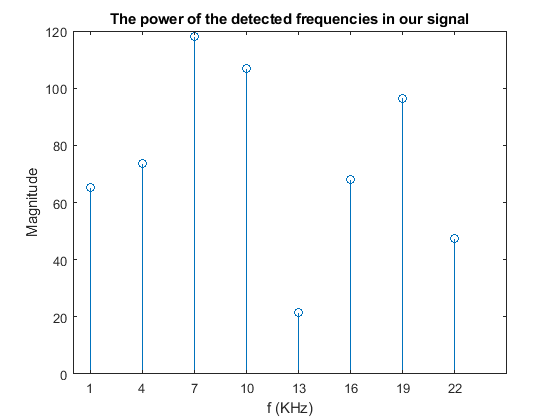

optimizedGoertzel(targetFreq,SR,noisySinus);

## IV-   Precomputed Constants


$$k\;=\left(\mathit{int}\right)\;\left(0\ldotp 5+\frac{N*\mathit{targetFreq}}{\mathit{SR}}\right)$$



$$\omega \;=2*\pi *\frac{k}{N}$$



$$\mathit{cosine}\;=\mathrm{cos}\left(\omega \right)$$



$$\mathit{sine}\;=\mathrm{sin}\left(\omega \right)$$



$$\mathit{coeff}\;=2*\mathit{cosine}$$


$Q_1$ and $Q_2$ must be initialized to zero at the beginning of each block of samples. For every *sample,* we need to run the following three equations : 


$$Q_0 \;=\mathit{coeff}*Q_1 -Q_2 +\mathit{sample}$$



$$Q_{2\;} =Q_1 \;$$



$$Q_{1\;} =Q_0$$


- For the basic Goertzel we obtain the results as showen below : 


$$\mathit{real}\;=Q_1 -Q_2 *\mathit{cosine}$$



$$\mathit{imaginary}\;=\;Q_2 *\mathit{sine}$$



$${\mathit{magnitude}}^2 \;={\mathit{real}}^{2\;} +{\mathit{imaginary}}^2$$


- For the optimized Goertzel :


$${\mathit{magintude}}^2 \;={Q_1 }^2 +{Q_2 }^2 -Q_1 *Q_2 *\mathit{coeff}$$


## Conclusion

- Problem

As we see in the code above that  the Goertzel algorithm capables to detect the presented frequencies in a signal, but as we increase the noise in the signal the detection of the frequencies decreases.

- Solution

As we increase the amplitude of our signal  as the power of detection frequencies increases.

#### References :

- [https://www.embedded.com/design/configurable-systems/4024443/The-Goertzel-Algorithm](https://www.embedded.com/design/configurable-systems/4024443/The-Goertzel-Algorithm)

- [https://en.wikipedia.org/wiki/Goertzel_algorithm](https://en.wikipedia.org/wiki/Goertzel_algorithm)

Create an optimizedGoertzel function that holds in the Goertzel algorithm.

function optimizedGoertzel(targetFreq,sampleRate,noisySignal)
    N = length(noisySignal);
    squareMagnitude(length(targetFreq)) = 0;

    for i = 1:length(targetFreq)
        k = round(0.5 + N*targetFreq(i)/sampleRate);
        w = 2*pi*k/N;
        cosine = cos(w);
        coeff = 2*cosine;
        Q2 = 0;
        Q1 = 0;
        for j = 1:N
            Q0 = noisySignal(j) + coeff*Q1 - Q2;
            Q2 = Q1;
            Q1 = Q0;
        end
        squareMagnitude(i) = Q1*Q1 + Q2*Q2 - Q1*Q2*coeff;
    end
    magnitude(length(targetFreq)) = 0;
    for r = 1:length(targetFreq)
        magnitude(r) = sqrt(squareMagnitude(r));
    end
  
    stem(targetFreq/1e3,magnitude)
    ax = gca;
    ax.XTick = targetFreq/1e3;
    xlabel('f (KHz)')
    ylabel('Magnitude')
    title('The power of the detected frequencies in our signal')
    save myResult.mat magnitude 
end